% get group cell arrays made first in a  seperate loop

% at this point, vars 4 indivisual & group analysis have already been created

% have matlab ask me how many mice I wanna average over for the present group
clear nGroup
nGroup = input('how many sessions in this group?')

nGroup =      3



% put that number into a for loop, have me get the var mat files that many of times

clear nthVarsFilePaths
clear n
for n = 1:nGroup
    
    [f p] = uigetfile('*.mat',sprintf('session # %0.00f vars4IndAndGroupAnalyses',n));
    
    % make cell array w/ sessions for columns
    % & file names/paths for values down the rows
    
    nthVarsFilePaths{1,n} = f;
    nthVarsFilePaths{2,n} = p;
    
    % load the nth var mat file
    load(fullfile(p,f));
    
    % put each var (could be a struct, double, etc) into a column of a cell array: 
    % all group cell arays will be % 1 x # sessions
    groupStimDetails{1,n} = stimDetails;
    groupSubjData{1,n} = subjData; 
    groupSubjName{1,n} = subjName;
    groupDate{1,n} = date;
    groupTrialCond{1,n} = trialCond;
    groupNumPreStimFrames{1,n} = numPreStimFrames;
    groupNumPostStimFrames{1,n} = numPostStimFrames;
    groupIdxOnsetsMeetsCriteria{1,n} = idxOnsetsMeetsCriteria;
    groupPeakFrameIdx{1,n} = peakFrameIdx;
    groupStimOnsetFrame{1,n} = stimOnsetFrame;
    groupBaselineIdx{1,n} = baselineIdx;
    groupBaselinedActIm{1,n} = baselinedActIm;
    groupRoundXpts{1,n} = RoundXpts;
    groupRoundYpts{1,n} = RoundYpts;
    groupPTSdfof{1,n} = PTSdfof;
    groupMeanSpeedAllTrials{1,n} = meanSpeedAllTrials;
    groupIdxRunTrials{1,n} = idxRunTrials;
    groupIdxStatTrials{1,n} = idxStatTrials;
    
end % now I have the group analysis vars for each session


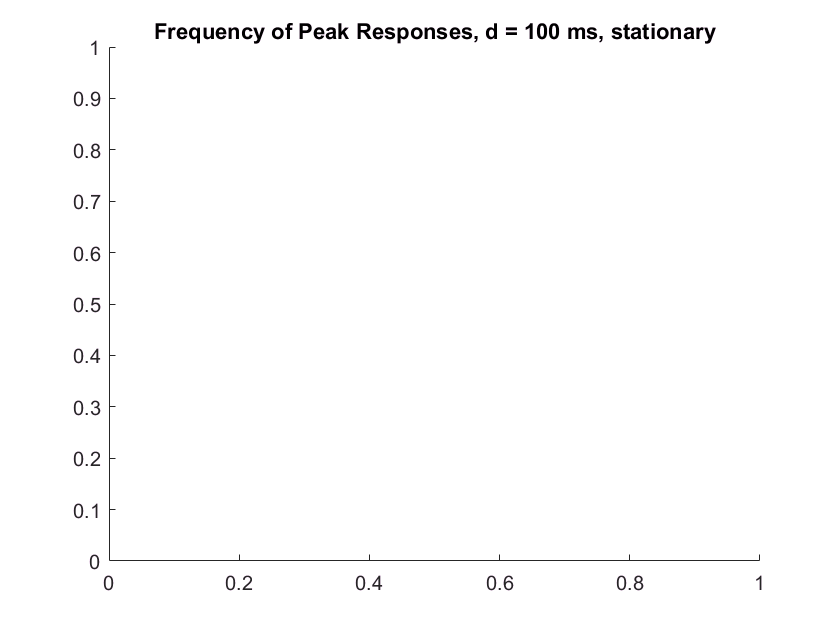

% one point, one dur, all cons, STATIONARY 

visArea = 1; % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 4; control

figure
title('Frequency of Peak Responses, d = 100 ms, stationary')


% NEED this for UNIQUE CONS for C loop:

% EXTRACT VARS from GROUP CELL ARRAYS
clear n
n = 1

n =      1


nthStimDetailsStruct = groupStimDetails{n};

Undefined variable "groupStimDetails" or class "groupStimDetails".


nthTrialCond = groupTrialCond{1,n};
nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n};

% CONTRAST calc's
clear con
clear conOrderedByTrial  
clear conOrderedByTrialMeetCriteria 
clear uniqueContrasts
clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end
conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueContrasts = unique(con); % for looping over contrast values later

%%  DURATION Calc's
clear dur
clear durOrderedByTrial  
clear durOrderedByTrialMeetCriteria 
clear uniqueDurations
% extract duration field from stimDetails
clear durs
for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end
durOrderedByTrial = dur(nthTrialCond); 
durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueDurations = unique(dur);

%% CON & DUR TOGETHER
clear conAndDur 
clear conAndDurOrderedByTrial 
clear conAndDurOrderedByTrialMeetCriteria
conAndDur = [con; dur];
conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);


clear d  % for each duration
for d = 1:length(uniqueDurations) % only 1 duration
            
    % for one POINT
    clear i 
    %for i = 2 % v1 
    for i = visArea

        clear c % for each contrast
        for c = 1:length(uniqueContrasts) 
            
            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
    
            clear n 
            for n = 1:nGroup % for each session/mouse
                
                % EXTRACT VARS from GROUP CELL ARRAYS
                nthStimDetailsStruct = groupStimDetails{n};
                nthTrialCond = groupTrialCond{1,n};
                nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n}; 
               
                % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
        
                % CONTRAST calc's
                clear con
                clear conOrderedByTrial  
                clear conOrderedByTrialMeetCriteria 
                clear uniqueContrasts
                clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
                for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
                    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
                end
                conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
                conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueContrasts = unique(con); % for looping over contrast values later
                
                %%  DURATION Calc's
                clear dur
                clear durOrderedByTrial  
                clear durOrderedByTrialMeetCriteria 
                clear uniqueDurations
                % extract duration field from stimDetails
                clear durs
                for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
                    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
                end
                durOrderedByTrial = dur(nthTrialCond); 
                durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueDurations = unique(dur);
        
                %% CON & DUR TOGETHER
                clear conAndDur 
                clear conAndDurOrderedByTrial 
                clear conAndDurOrderedByTrialMeetCriteria
                conAndDur = [con; dur];
                conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
                conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                
                % in preparation for making pixel wise figures of fluroescene at different stim conditions,
                % make figure legends
                [reigons,cons4Legend,cons4axes,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
                % durs4Legend = {'16 ms','33 ms', '66 ms', '133 ms', '266 ms'}
                durs4Legend = {'100 ms'};
        
                % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
                nthPTSdfof = groupPTSdfof{1,n};
                nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
                nthBaselineIdx = groupBaselineIdx{1,n};
                
                % EXTRACT RUN vs STAT TRIAL INDICIES
                nthIdxRunTrials = groupIdxRunTrials{1,n};
                nthIdxStatTrials = groupIdxStatTrials{1,n}; 
        
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthSTATtrials = intersect(idxCthDthTrial,nthIdxStatTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthSTATtrials = length(idxCthDthSTATtrials);
                
                % GET DFof for PEAK FRAMES
                
                % take df/f data for ith pt, peak frames, cth dth stat trials
                allPeakFramesCthDthTrialsIthPt = squeeze(nthPTSdfof(i,nthPeakFrameIdx,idxCthDthSTATtrials)); 
                meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
                % ^ CANT do: store output vectors for each contrast
                % b/c every vectoris a different length (num trials), so can't 'collect'
                % Better to just plot directly on the subplot here
                    
                % get BASELINE @ cth dth state trials
                
                clear allBaselineFrames
                allBaselineFrames = squeeze(nthPTSdfof(i,nthBaselineIdx,idxCthDthSTATtrials));
                % get one mean baseline value over all frames & trials
                meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
                meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
                
                % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
        
                meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
                % ^this is a 1 x # trials vector
                    
                % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
                % we can't store in a session matrix. 
                % but, since this is a group analysis, and since I'm not calulating stderr, 
                % I can concatenate each session's trials at a particular contrast and plot one
                % subplot/contrast at a time
                
                % SAVE EACH CTH mean Df for peck frames of cth dth stat trials
                
                allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
                
                length(allSessCthPeakDfEachTrial);
                
            end % end n loop - have vector for all trials across all sessions at 1 contrast now
                
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            subplot(2,4,c) % make a subplot for each contrast
            title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            numBins = 25;
            histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability')
            title(uniqueContrasts(c))
            xlabel('peak df/f')
            ylabel('percentage of trials')
            ylim([0 0.18])
            xlim([-0.09 0.18])
            
            set(gca,'XTick',-0.1:0.05:0.2)
           % set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            hold on  
                    
        end % end c loop - move to next contrast/subplot
                
    end % end i loop (only 1 point
    
end % end d loop (only 1 dur)
                    
numTrialsOneCon = size(allSessCthPeakDfEachTrial)

% one point, one dur, all cons, RUNNING

figure
title('Frequency of Peak Responses, d = 100 ms, running')

% NEED this for UNIQUE CONS for C loop:

% EXTRACT VARS from GROUP CELL ARRAYS
clear n
n = 1
nthStimDetailsStruct = groupStimDetails{n};
nthTrialCond = groupTrialCond{1,n};
nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n};

% CONTRAST calc's
clear con
clear conOrderedByTrial  
clear conOrderedByTrialMeetCriteria 
clear uniqueContrasts
clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end
conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueContrasts = unique(con); % for looping over contrast values later

%%  DURATION Calc's
clear dur
clear durOrderedByTrial  
clear durOrderedByTrialMeetCriteria 
clear uniqueDurations
% extract duration field from stimDetails
clear durs
for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end
durOrderedByTrial = dur(nthTrialCond); 
durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
uniqueDurations = unique(dur);

%% CON & DUR TOGETHER
clear conAndDur 
clear conAndDurOrderedByTrial 
clear conAndDurOrderedByTrialMeetCriteria
conAndDur = [con; dur];
conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);


clear d  % for each duration
for d = 1:length(uniqueDurations) % only 1 duration
            
    % for one POINT
    clear i 
    for i = 1 % v1 

        clear c % for each contrast
        for c = 1:length(uniqueContrasts) 
            
            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
    
            clear n 
            for n = 1:nGroup % for each session/mouse
                
                % EXTRACT VARS from GROUP CELL ARRAYS
                nthStimDetailsStruct = groupStimDetails{n};
                nthTrialCond = groupTrialCond{1,n};
                nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n}; 
               
                % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
        
                % CONTRAST calc's
                clear con
                clear conOrderedByTrial  
                clear conOrderedByTrialMeetCriteria 
                clear uniqueContrasts
                clear cons % % still in session loop, for each stim condition, get contrast value, store all in vector
                for cons = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
                    con(cons) = nthStimDetailsStruct(cons).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
                end
                conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
                conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueContrasts = unique(con); % for looping over contrast values later
                
                %%  DURATION Calc's
                clear dur
                clear durOrderedByTrial  
                clear durOrderedByTrialMeetCriteria 
                clear uniqueDurations
                % extract duration field from stimDetails
                clear durs
                for durs = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
                    dur(durs) = nthStimDetailsStruct(durs).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
                end
                durOrderedByTrial = dur(nthTrialCond); 
                durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                uniqueDurations = unique(dur);
        
                %% CON & DUR TOGETHER
                clear conAndDur 
                clear conAndDurOrderedByTrial 
                clear conAndDurOrderedByTrialMeetCriteria
                conAndDur = [con; dur];
                conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
                conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
                
                % in preparation for making pixel wise figures of fluroescene at different stim conditions,
                % make figure legends
                [reigons,cons4Legend,cons4axes,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
                % durs4Legend = {'16 ms','33 ms', '66 ms', '133 ms', '266 ms'}
                durs4Legend = {'100 ms'};
        
                % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
                nthPTSdfof = groupPTSdfof{1,n};
                nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
                nthBaselineIdx = groupBaselineIdx{1,n};
                
                % EXTRACT RUN vs STAT TRIAL INDICIES
                nthIdxRunTrials = groupIdxRunTrials{1,n};
                nthIdxStatTrials = groupIdxStatTrials{1,n}; 
        
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthRUNtrials = intersect(idxCthDthTrial,nthIdxRunTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthRUNtrials = length(idxCthDthRUNtrials)
                
                % GET DFof for PEAK FRAMES
                
                % take df/f data for ith pt, peak frames, cth dth stat trials
                allPeakFramesCthDthTrialsIthPt = squeeze(nthPTSdfof(i,nthPeakFrameIdx,idxCthDthRUNtrials)); 
                meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
                % ^ CANT do: store output vectors for each contrast
                % b/c every vectoris a different length (num trials), so can't 'collect'
                % Better to just plot directly on the subplot here
                    
                % get BASELINE @ cth dth state trials
                
                clear allBaselineFrames
                allBaselineFrames = squeeze(nthPTSdfof(i,nthBaselineIdx,idxCthDthRUNtrials));
                % get one mean baseline value over all frames & trials
                meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
                meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
                
                % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
        
                meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
                % ^this is a 1 x # trials vector
                    
                % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
                % we can't store in a session matrix. 
                % but, since this is a group analysis, and since I'm not calulating stderr, 
                % I can concatenate each session's trials at a particular contrast and plot one
                % subplot/contrast at a time
                
                % SAVE EACH CTH mean Df for peck frames of cth dth stat trials
                
                allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
                
                length(allSessCthPeakDfEachTrial);
                
            end % end n loop - have vector for all trials across all sessions at 1 contrast now
                
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            subplot(2,4,c) % make a subplot for each contrast
            title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            numBins = 25;
            histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability')
            title(uniqueContrasts(c))
            xlabel('peak df/f')
            ylabel('percentage of trials')
            ylim([0 0.18])
            xlim([-0.09 0.18])
            
            set(gca,'XTick',-0.1:0.05:0.2)
           % set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            hold on  
                    
        end % end c loop - move to next contrast/subplot
                
    end % end i loop (only 1 point
    
end % end d loop (only 1 dur)
                    
numTrialsOneCon = size(allSessCthPeakDfEachTrial)